# **RS-WISP-02: RPOD Code Demonstration**

**WorkerInSpace**

**Hongseok Kim**

## **I. Scope**

  Demonstrate example Rendezvous simulation using C-W equation in 2-body Kepler Dynamics.

### II. RPOD Algorithm

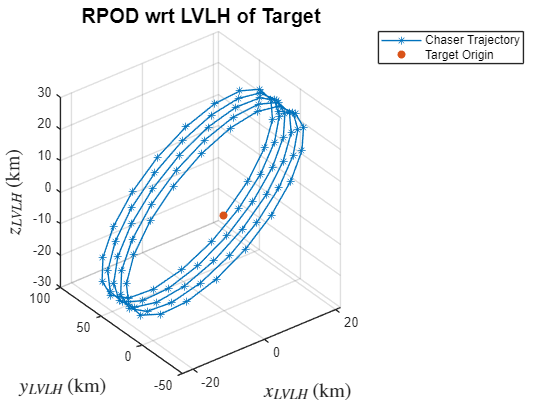

%% Input Parameters

% Target Information
Target.a = 300+6378;
Target.e = 1e-5;
Target.i = 40;
Target.RAAN = 20;
Target.AOP = 0;
Target.TA = 60;


% Chaser Information
Chaser.a = 6378 + (318.5 + 515.51)/2;
Chaser.e = (6378+515.51)/Chaser.a-1;
Chaser.i = 40.130;
Chaser.RAAN = 19.819;
Chaser.AOP = 70.662;
Chaser.TA = 349.65;

% Timing of Docking
t_f = 28800;

%% Main Algorithm

% Change to ECI frame

% rv data of the target wrt ECI
[r_0,v_0] = kepler2ijk_hs(Target.a, Target.e, Target.i, Target.RAAN, Target.AOP, Target.TA);

% rc data of the chaser wrt ECI
[r,v] = kepler2ijk_hs(Chaser.a, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA);

% Reference Frame of the Target
i_hat = r_0/norm(r_0);
j_hat = v_0/norm(v_0);
k_hat = cross(i_hat, j_hat);

% Transformation Matrix from ECI to Space Station Frame
Q_Xx = [i_hat';j_hat';k_hat'];

% Position vector of the spacecraft relative to the space station (ECI)
delta_r = r - r_0;
n = norm(v_0)/norm(r_0);
Omega_target = n * k_hat;
delta_v = v - v_0 - cross(Omega_target, delta_r);

% Relative position vector at the beginning of the rendezvous maneuver
delta_r_0 = Q_Xx * delta_r;

% Relative velocity just before launch into the rendezvous trajectory is
delta_v_0_minus = Q_Xx * delta_v;

% Calculate Clohessy-Whiltshire matrix for t = t_f = 28800s and n
[Phi_rr_tf, Phi_rv_tf, Phi_vr_tf, Phi_vv_tf] = cw_matrix_generator(n,t_f);

delta_v_0_plus = -inv(Phi_rv_tf) * Phi_rr_tf * delta_r_0;
delta_v_f_minus = Phi_vr_tf * delta_r_0 + Phi_vv_tf * delta_v_0_plus;

% Delta-v at the beginning of the rendezvous maneuver
Delta_v_0 = delta_v_0_plus - delta_v_0_minus;
% Delta-v at the conclusion of the maneuver
Delta_v_f = [0;0;0] - delta_v_f_minus;


% Total Delta-v requirement is
Delta_v_total = norm(Delta_v_0) + norm(Delta_v_f);
% Drawing Reference Chaser Trajector wrt Target

t_vector = linspace(0,t_f);
delta_r_t_mat = zeros(length(t_vector),3);

for timestep = 1:length(t_vector)

    t = t_vector(timestep);

    [Phi_rr_t, Phi_rv_t, Phi_vr_t, Phi_vv_t] = cw_matrix_generator(n,t);

    delta_r_t = Phi_rr_t * delta_r_0 + Phi_rv_t * delta_v_0_plus;

    delta_r_t_mat(timestep,:) = delta_r_t';

end


figure;
plot3(delta_r_t_mat(:,1),delta_r_t_mat(:,2),delta_r_t_mat(:,3),'*-')
hold on
scatter3(0,0,0,'filled','o')
hold off
grid on
title('RPOD wrt LVLH of Target','FontSize',15,'FontWeight','bold')
xlabel('$x_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
legend('Chaser Trajectory', 'Target Origin')

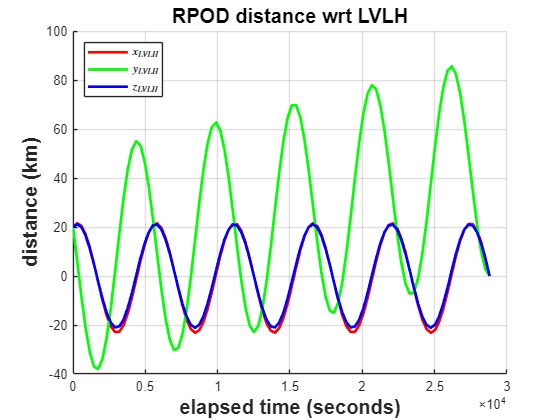

figure;
hold on
plot(t_vector, delta_r_t_mat(:,1),'r','LineWidth',2)
plot(t_vector, delta_r_t_mat(:,2),'g','LineWidth',2)
plot(t_vector, delta_r_t_mat(:,3),'b','LineWidth',2)
hold off
title('RPOD distance wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
ylabel('distance (km)','FontSize',15,'FontWeight','bold')
legend('$x_{LVLH}$','$y_{LVLH}$','$z_{LVLH}$', 'Interpreter', 'latex','Location','northwest')
grid on

from 


$$\begin{array}{l}
\delta \mathit{\mathbf{v}}=\mathit{\mathbf{v}}-{\mathit{\mathbf{v}}}_0 -n\hat{\mathbf{k}} \times \delta \mathit{\mathbf{r}}\\
\mathit{\mathbf{v}}={\mathit{\mathbf{v}}}_0 +n\hat{\mathbf{k}} \times \delta \mathit{\mathbf{r}}+\delta \mathit{\mathbf{v}}\\
\mathrm{note}:\delta \mathit{\mathbf{v}}={\left({\left\lbrack Q\right\rbrack }_{\mathrm{Xx}} \right)}^{-1} \left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack 
\end{array}$$


% Get Inertial Chaser's velocity after initial burn
v_plus = v_0 + cross(Omega_target, delta_r) + inv(Q_Xx)*delta_v_0_plus;

tVec = 1:1:t_f;
n = length(tVec);

% Propaget Target and Chaser under 2-body dynamics
[t,y_chaser] = orbit_propagation(r, v_plus, tVec);
[t,y_target] = orbit_propagation(r_0, v_0, tVec);

y_chaser(end,:)

ans = 1.0e+03 *

   -6.4945   -1.3188    0.8241    0.0006   -0.0059   -0.0049


y_target(end,:)

ans = 1.0e+03 *

   -6.4942   -1.3221    0.8213    0.0006   -0.0060   -0.0049


y_chaser(end,1:3) - y_target(end,1:3)

ans =    -0.3502    3.2859    2.8560


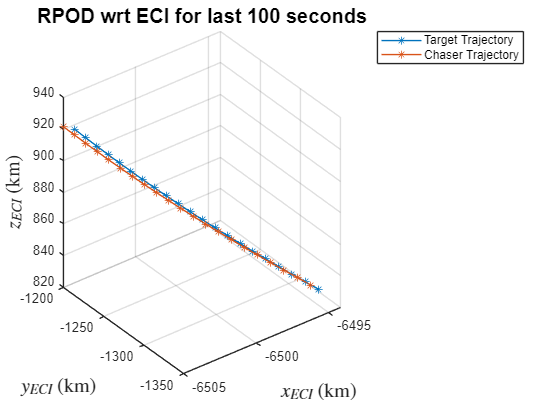

delta_t = 20;

figure;
plot3(y_target(n-delta_t:n,1),y_target(n-delta_t:n,2),y_target(n-delta_t:n,3),'*-')
hold on
plot3(y_chaser(n-delta_t:n,1),y_chaser(n-delta_t:n,2),y_chaser(n-delta_t:n,3),'*-')
hold off
grid on
title('RPOD wrt ECI for last 100 seconds','FontSize',15,'FontWeight','bold')
xlabel('$x_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
legend('Target Trajectory', 'Chaser Trajectory')

## Appendix 1: Clohessy-Wilshire Matrix Generator 

function [Phi_rr, Phi_rv, Phi_vr, Phi_vv] = cw_matrix_generator(n,t)

nt = n*t;

Phi_rr = [4 - 3*cos(nt),   0, 0;
          6*(sin(nt) - nt),1,0;
          0,0, cos(nt)];

Phi_rv = [sin(nt)/n, 2/n * (1 - cos(nt)), 0;
          2/n*(cos(nt)-1), 4/n*sin(nt)-3*t,0;
          0,0,1/n*sin(nt)];

Phi_vr = [3*n*sin(nt),0,0;
          6*n*(cos(nt)-1),0,0;
          0,0,-n*sin(nt)];
Phi_vv = [cos(nt), 2*sin(nt),0
         -2*sin(nt), 4*cos(nt)-3, 0;
          0,0,cos(nt)];
end

## Appendix 2: Bundle Functions (kepler2ijk, ijk2kepler)

function [r,v] = kepler2ijk_hs(a,e,inc,RAAN,AOP,theta)

mu = 398600.4415;

RAAN = RAAN/180*pi;
inc = inc/180*pi;
AOP = AOP/180*pi;
theta = theta/180*pi;


R_3_AOP = [cos(AOP), sin(AOP),0;
           -sin(AOP), cos(AOP),0;
                    0,       0,1];

R_1_inc = [1,       0,         0;
           0, cos(inc),  sin(inc);
           0,-sin(inc),  cos(inc)];

R_3_RAAN = [cos(RAAN), sin(RAAN),0;
           -sin(RAAN), cos(RAAN),0;
                    0,       0,1];


Q_rotation = R_3_AOP * R_1_inc * R_3_RAAN;

p = Q_rotation(1,:);
q = Q_rotation(2,:);
w = Q_rotation(3,:);

p_value = a*(1-e^2);
r = p_value* (cos(theta)*p + sin(theta) *q)/(1+e*cos(theta));
r = r';
v = sqrt(mu/p_value)*(-sin(theta)*p+(e+cos(theta))*q)';
end


function [a, e, inc, RAAN, AOP, theta] = ijk2kepler_hs(r,v)

mu = 398600.4415;

h = cross(r,v);                                   % Angular Velocity Vector
z = [0,0,1]';
n = (cross(z,h))/(norm(cross(z,h)));              % Normal Vector
e_vector = ((cross(v,h))/mu) - r/(norm(r));       % Eccentricity vector


a = (-mu)/((norm(v))^2 - 2*mu/norm(r));           % 1. Semi-major axis
e = norm(e_vector);                               % 2. Eccentricity
inc = acos(dot(z,h)/norm(h)) / pi *180;           % 3. Inclination

RAAN = atan2(n(2),n(1));                          % 4. RAAN
RAAN = RAAN / pi * 180;

AOP = acos((dot(n,e_vector))/norm(e_vector));                   % 5. Argument of periapse
if(e_vector(3)<0)
    AOP = 2*pi - AOP;
end
AOP = AOP/pi*180;

theta = acos((dot(r,e_vector))/(norm(r)*norm(e_vector)));       % 6. True anomaly
if(dot(r,v) < 0)
    theta = 2*pi-theta;
end
theta = theta / pi * 180;

end

## Appendix 3: 2-body orbit propagator in ECI

function dydt = two_body_dynamics(t,y)

 % Define the standard gravitational parameter for Earth (km^3/s^2)
    mu = 398600.4415;
 
 % Extract position and velocity from the input state vector
    r_vec = y(1:3); % Position vector
    v_vec = y(4:6); % Velocity vector

 % Calculate the norm of the position vector
    r_norm = norm(r_vec);

 % Compute the acceleration based on the gravitational force
   a1 = -mu*r_vec(1)/(r_norm^3);
   a2 = -mu*r_vec(2)/(r_norm^3);
   a3 = -mu*r_vec(3)/(r_norm^3);

 % Combine velocity and acceleration to form the derivative of the state vector
    dydt = [v_vec; a1;a2;a3];
end



function [t,y] = orbit_propagation(r0, v0, tVec)

    odeoptions = odeset('RelTol',1e-10,'AbsTo',1e-20);
    % Calculate the magnitude of the position and velocity vectors
    y0 = [r0;v0];
    
    % Solve the ODE using ode45
    [t, y] = ode45(@two_body_dynamics, tVec, y0, odeoptions);
end